# EJERCICIO 3 (Opción B)

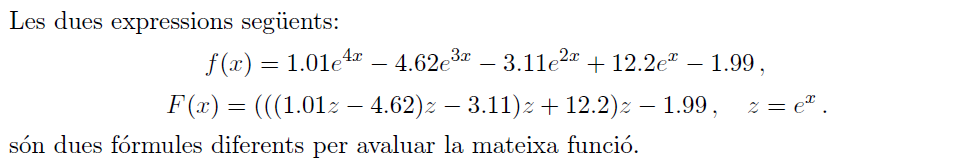

clear vars
format shortG
RESULT = [];

% Funcion para redondear a 3 cifras significativas (del ejercicio 2)
x = 1.53; n = 3;
f1 = f(x,n);
F1 = F(x,n);

RESULT = [RESULT; x n f1 F1];

x = 0.925; n = 4;
f2 = f(x,n);
F2 = F(x,n);

RESULT = [RESULT; x n f2 F2];

% Evaluacion sin redondeos (aritmetica de MATLAB)
F_real = @(x) (((1.01*exp(1)^x - 4.62)*exp(1)^x - 3.11)*exp(1)^x + 12.2)*exp(1)^x - 1.99;


f1_Matlab = F_real(1.53);
f2_Matlab = F_real(0.925);

[~,~,epf1] = funerror(f1,f1_Matlab);
[~,~,epF1] = funerror(F1,f1_Matlab);
[~,~,epf2] = funerror(f2,f2_Matlab);
[~,~,epF2] = funerror(F2,f2_Matlab);

RESULT = [RESULT(:,1:2) [f1_Matlab; f2_Matlab] RESULT(:,3:4) [[epf1 epF1]; [epf2 epF2]]];

array2table(RESULT', "RowNames", {'x', 'n', 'f(x)_matlab', 'f(x,n)', 'F(x,n)', 'ep_f', 'ep_F'}, "VariableNames", {'Ejercicio 1', 'Ejercicio 2'})

ans = 7×2 table
                   Ejercicio 1    Ejercicio 2
                   ___________    ___________

    x                   1.53           0.925 
    n                      3               4 
    f(x)_matlab      -7.6079         -24.249 
    f(x,n)             -6.79          -24.25 
    F(x,n)             -7.07          -24.26 
    ep_f               10.75       0.0044321 
    ep_F              7.0699        0.045671 


function y = f(x, n)
% Evalua la funcion f en x con una aritmetica de n digitos por redondeo
    
    R = @(x) myRound(x,n);
    
    % Calculo de las potencias de euler
    % [Ejemplo: e^(4x) -> (e^x)^4 -> (e^x)(e^x)(e^x)(e^x)]
    e1 = R(exp(x));
    e2 = R(e1 * e1);
    e3 = R(e2 * e1);
    e4 = R(e3 * e1);
    
    % Calculo de los productos
    a = R(1.01 * e4);
    b = R(4.62 * e3);
    c = R(3.11 * e2);
    d = R(12.2 * e1);
    
    % Calculo de sumas y restas
    y = R(R(R(R(a - b) - c) + d) - 1.99);
end 


function y = F(x, n)
% Evalua la funcion F en x con una aritmetica de n digitos por redondeo
        
    R = @(x) myRound(x,n);
    
    z = R(exp(x));
    a = R(1.01 * z);
    b = R(R(a - 4.62) * z);
    c = R(R(b - 3.11) * z);
    d = R(R(c + 12.2) * z);
    y = R(d - 1.99);
end